# 确认LOG频率

故障未知仿真log的unknown_logger频率是50Hz

这里替换log中的时间采用相对时间

clc
logSampleRate = 50;
 
ulogOBJ = ulogreader("log_0_2021-6-30-08-07-24.ulg");
msg = readTopicMsgs(ulogOBJ);

# 确定unknown_logger的序号，提取log数据

更换log文件后需要修改下面的数值，找到msg中对应的unknown_logger的序号是多少。

 
% 获取unknown_logger数据
unknown_logger = msg.TopicMessages{32};
% 生成相对时间
log_time = unknown_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));
% 获取具体数据
h1 = unknown_logger.h1;
h2 = unknown_logger.h2;
h1d = unknown_logger.h1d;
h2d = unknown_logger.h2d;
uest = unknown_logger.uest;
uref = unknown_logger.uref;
chvDes = unknown_logger.chvdes;
tDes = unknown_logger.tdes;
psi = unknown_logger.psi;

% 出图
% figure(1)
% plot(relativeTime, h1, relativeTime, h1d);
% figure(2)
% plot(relativeTime, h2, relativeTime, h2d);

# 画出主轴的跟踪图

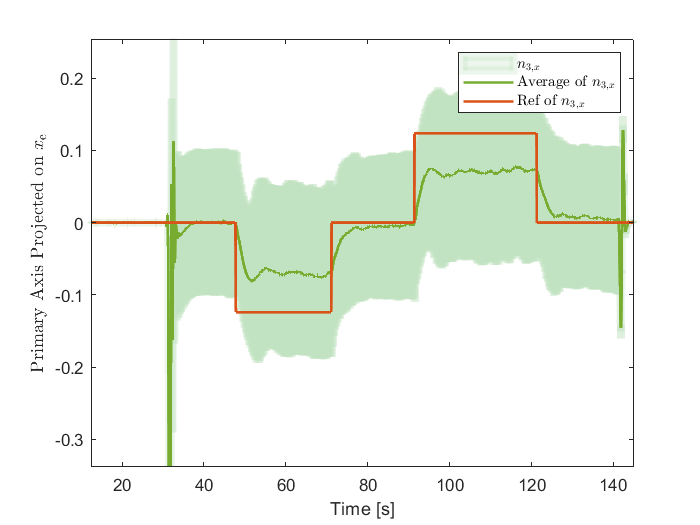

 

% 进行滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2,'SampleRate',50);
h1f = filtfilt(d,double(h1));
% 滤波出图
figure(3)
clf
area(relativeTime,h1,'FaceColor','#c0e2c0','EdgeColor','#c0e2c0','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5)
hold on
plot(relativeTime,h1f,'Color','#77AC30','LineWidth',1.5)
plot(relativeTime,h1d,'Color','#D95319','LineWidth',1.5)

legend('$n_{3,x}$','Average of $n_{3,x}$','Ref of $n_{3,x}$',"Interpreter","latex")
xlabel("Time [s]")
ylabel("Primary Axis Projected on $x_{\mathrm{e}}$","Interpreter","latex")

xlim([36.0 138.4])
ylim([-0.226 0.232])


% legend('Box',"off")

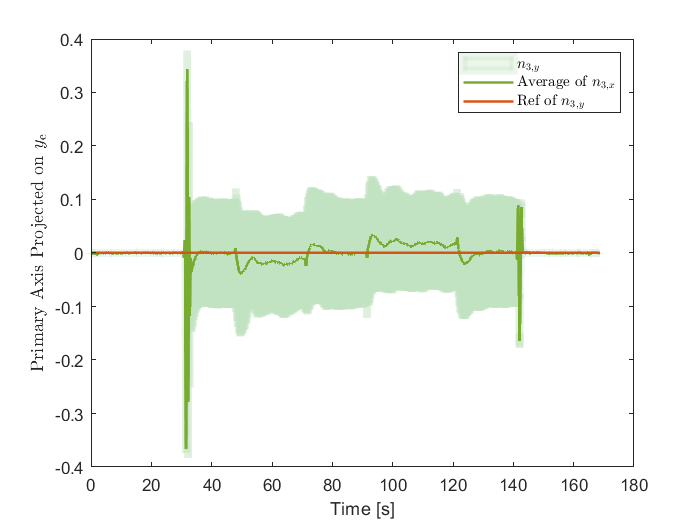

 

% 进行滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2,'SampleRate',50);
h2f = filtfilt(d,double(h2));
% 滤波出图
figure(3)
clf
area(relativeTime,h2,'FaceColor','#c0e2c0','EdgeColor','#c0e2c0','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5)
hold on
plot(relativeTime,h2f,'Color','#77AC30','LineWidth',1.5)
plot(relativeTime,h2d,'Color','#D95319','LineWidth',1.5)

legend('$n_{3,y}$','Average of $n_{3,x}$','Ref of $n_{3,y}$',"Interpreter","latex")
xlabel("Time [s]")
ylabel("Primary Axis Projected on $y_{\mathrm{e}}$","Interpreter","latex")

# 角速率跟踪图

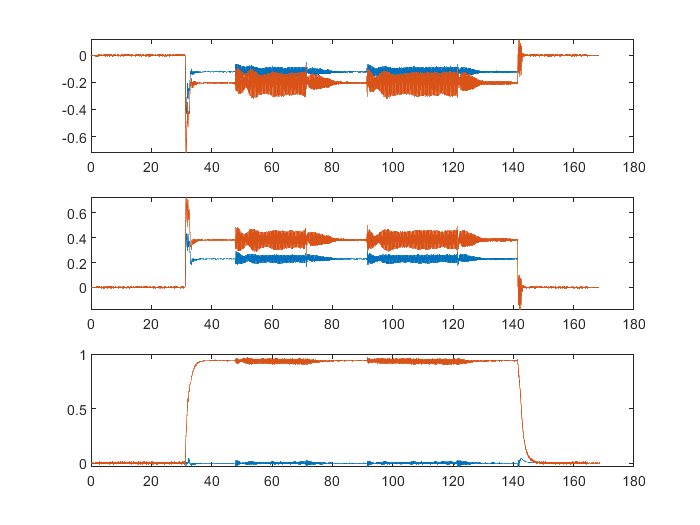

 

figure(4)
clf
subplot(3,1,1)
plot(relativeTime,uest(:,1),relativeTime,uref(:,1))
subplot(3,1,2)
plot(relativeTime,uest(:,2),relativeTime,uref(:,2))
subplot(3,1,3)
plot(relativeTime,uest(:,3),relativeTime,uref(:,3))

这部分与前面部分无关系，使用单独的log文件

进行单独前飞位置环的HIL仿真，画出方位角与电机转速的关系图（只有姿态环的话效果不好。）

 
logSampleRate = 50;
ulogOBJ = ulogreader("log_2_2021-6-30-08-31-52.ulg");
msg = readTopicMsgs(ulogOBJ);

 
% 获取unknown_logger数据
unknown_logger = msg.TopicMessages{28};
% 生成相对时间
log_time = unknown_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));
% 获取具体数据
% h1 = unknown_logger.h1;
% h2 = unknown_logger.h2;
% h1d = unknown_logger.h1d;
% h2d = unknown_logger.h2d;
% uest = unknown_logger.uest;
% uref = unknown_logger.uref;
% chvDes = unknown_logger.chvdes;
tDes = unknown_logger.tdes;
psi = unknown_logger.psi;

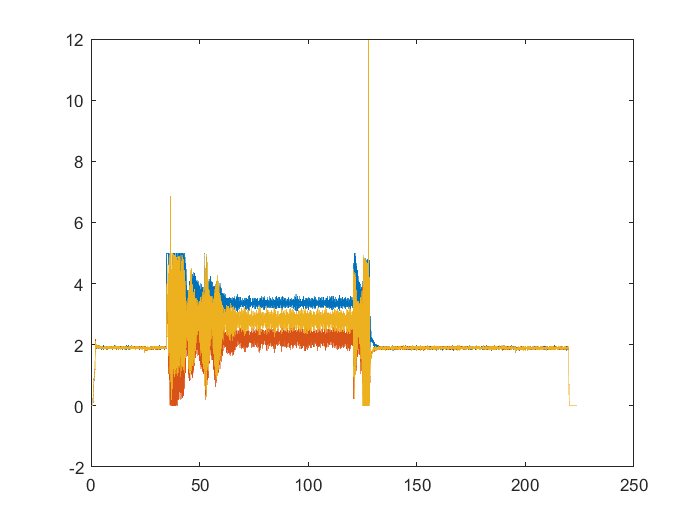

 

figure(5)
clf
plot(relativeTime,tDes(:,1),relativeTime,tDes(:,2),relativeTime,tDes(:,4))

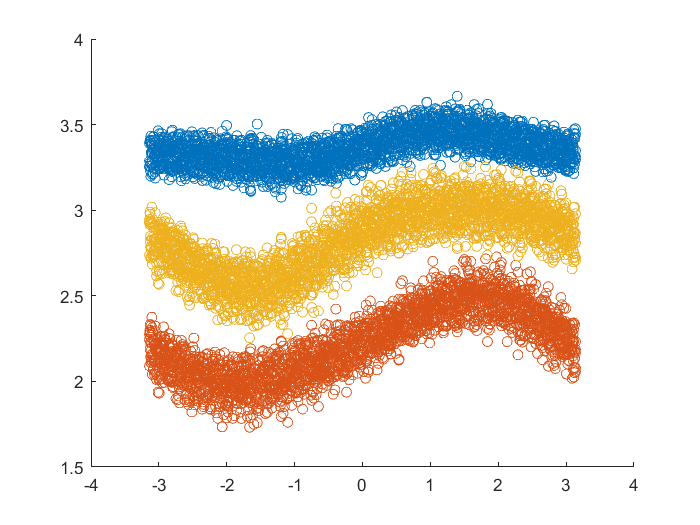

clf
tstart = 70;%采样开始时间
tend = 120;%采样结束时间
samplevector = tstart*logSampleRate:tend*logSampleRate;

scatter(psi(samplevector),tDes(samplevector,1))
hold on
scatter(psi(samplevector),tDes(samplevector,2))
hold on
% scatter(psi(40*50:40*80),tDes(40*50:40*80,3))
% hold on
scatter(psi(samplevector),tDes(samplevector,4))